# Linear Quadratic Regulator (LQR)

In this script, we will explore the application of Linear Quadratic Regulator (LQR) control on a DC motor to regulate its angular velocity using MATLAB Live Script. The process will involve the following key steps:

- Analyze the open-loop system: Understand the dynamics and behavior of the DC motor without any control.

- Apply LQR control to meet requirements: Design and implement the LQR controller to achieve desired performance and stability criteria.

- Use it to meet additional constraints: Adjust the LQR design to satisfy additional constraints such as minimizing energy consumption.

By following these steps, you will gain hands-on experience in designing and tuning LQR controllers for practical applications.

## Review the system

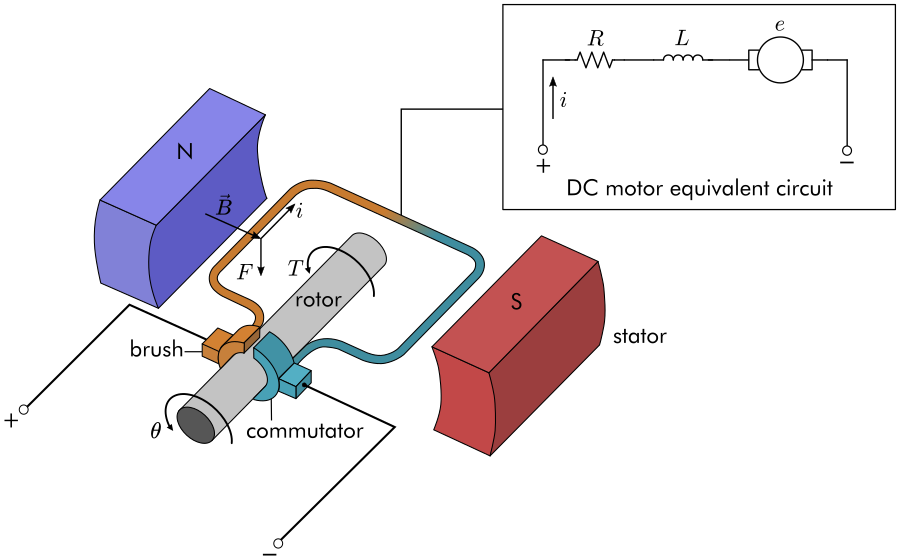


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$


 
$$J \ddot{\theta} + b \dot{\theta}  = k_m i$$
      

We will assume $K = k_e = k_m$

### State space model

- The armature voltage is treated as the input and the rotational speed is chosen as the output

- The state-space representation is therefore:

State vector: $\mathbf{x} = \left[ \begin{array}{c} 
\dot{\theta} \\
i

\end{array} \right]$


$$\dot{\mathbf{x}}  = \left[ \begin{array}{c} 
\ddot{\theta} \\
\dot{i}
\end{array} \right]   =  \left[ \begin{array}{cc}
-\frac{b}{J} &  \frac{K}{J} \\
-\frac{K}{L} & -\frac{R}{L} 
\end{array} \right] \left[ \begin{array}{c} 
\dot{\theta} \\
i
\end{array} \right]

  +  \left[ \begin{array}{c} 
0 \\
\frac{1}{L}  
\end{array} \right] v  \\ 
\dot{\mathbf{x}} = A\mathbf{x}  + Bu$$



$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] 
\left[ \begin{array}{c} 
\dot{\theta} \\ 
i
\end{array} \right] \\

y = C\mathbf{x} + Du$$


### Analyze open loop system

#### Initializing motor parameters

J = 0.01; %kg.m^2
b = 0.1; %N.m.s 
K = 0.01; %V/rad/s
R = 1; %Ohm
L = 0.5; %H


#### Setting up the state space object 

%setting up the state space model 
A = [-b/J, K/J; -K/L -R/L]; 
B = [0; 1/L]; 
C = [1 0];
D = 0;
dcMotorSS = ss(A,B,C,D); 

#### Step response

Compute settling time

info = stepinfo(dcMotorSS); 
openLoopSetTime = info.SettlingTime;

Goal: get it under 2 seconds 

### Designing the state feedback controller 

#### Compute feedback gain using LQR

Q1 = 61;
Q2 = 1

Q2 = 1

Q = diag([Q1,Q2]); 
R = 1

R = 1

Kc = lqr(dcMotorSS,Q,R);

#### New settling time

sys_cl = ss(A-B*Kc,B,[1,0],D); 
info = stepinfo(sys_cl); 
ClosedLoopSetTime = info.SettlingTime;
steadyState = dcgain(sys_cl); 
voltageInput = 1/steadyState; 

#### Observing current

sys_cl_i = ss(A-B*Kc,B,[0,1],D); 
currDcGain = dcgain(sys_cl_i); 
peakCurr = stepinfo(sys_cl_i); 
peakCurr = peakCurr.Peak;

variableNames = {'openLoopSetTime','ClosedLoopSetTime','voltageInput', 'peakCurr' };
values = [openLoopSetTime,ClosedLoopSetTime,voltageInput,peakCurr];
T = array2table(values, 'VariableNames',variableNames); 
disp(T)

    openLoopSetTime    ClosedLoopSetTime    voltageInput    peakCurr
    _______________    _________________    ____________    ________
        2.0652              1.3166             16.162       0.61834 


## Conclusion

In conclusion, our exercise on adjusting the penalties in the Q matrix for LQR control on a DC motor demonstrates the following trade-offs:

Adjusting the penalty for angular velocity

  - Reduces the settling time.

  - Results in increased voltage.

Adjusting the penalty for current:

  - Reduces the peak current.

  - Results in increased voltage.

Maintaining low voltage:

  - Increases both settling time and peak current.

These insights highlight the importance of carefully tuning the LQR parameters to balance performance criteria such as settling time, peak current, and voltage levels based on the specific requirements of your control system. 

You can also come up with your logic to adjust the weight (in what sequence, step length, etc) to automate the process. Note however that this logic will highly dependent on the specific system you are working with. 